# Course vs. Fine Grids

% This example demonstrates the difference between an course and fine grid. The demo was rewritten from the RegularizeData3D demos.

clc; clear; close all;

## Input points.

inputPoints =[
	1,  0.5, 0.5;
	1,    2,   1;
	1,  3.5, 0.5;
	3, 0.75, 0.5;
	3,  1.5,   1;
	3, 2.25, 0.5;
	3,    3,   1;
	3,    4, 0.5];

## Calculate Surface over Course and Fine Mesh

% Change the spacing to test each axis or both axes. You get the same
% surface profile whether the spacing is 0.5 or 0.01 on either or both
% axes.
xCourse = 0:0.2:4;
yCourse = 0:0.4:4;

% Now use a really fine mesh.
xFine = 0:0.02:4;
yFine = 0:0.04:4;

% Set the smoothness.  See the documentation for details about the
% smoothness setting. This demonstration shows that the surfaces are
% equivalent when they have the same smoothing.
smoothness = 0.001;

% Use the regularizeNd with cubic interpolation.
zCourse = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {xCourse, yCourse}, smoothness, 'cubic');
% other equivalent calls
% zCourse = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {xCourse, yCourse}, smoothness, 'cubic',[]);
% zCourse = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {xCourse, yCourse}, smoothness, 'cubic', 'normal');

% call regularizeNd for the fine mesh.
zFine = regularizeNd(inputPoints(:, 1:2), inputPoints(:, 3), {xFine, yFine}, smoothness, 'cubic');

## Plot

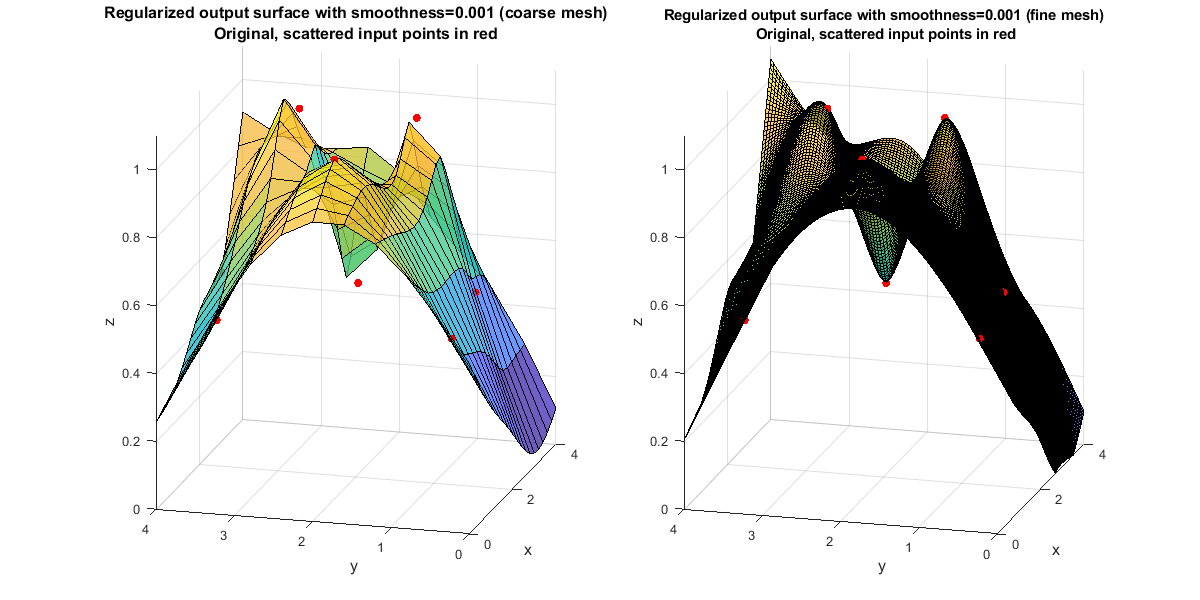

screenSize = get(groot, 'screenSize');
figurePosition = screenSize(3:4)*0.1;
figureSize = [1200 600];
figurePositionAndSize = [figurePosition figureSize];
figure('color', 'w', 'position', figurePositionAndSize)

% Plot this figure on the left.
subplot1 = subplot(1, 2, 1);
view(subplot1, [-74.5, 14]);
grid(subplot1, 'on');
hold(subplot1, 'all');

% Note that surf uses the meshgrid format for plotting surfaces using
% vectors for x and y. regularizeNd outputs in the ndgrid format. In 2d,
% meshgrid is the transpose of the ndgrid format.
surf(xCourse, yCourse, zCourse', 'facealpha', 0.75);
scatter3(inputPoints(:, 1), inputPoints(:, 2), inputPoints(:, 3),[], 'r', 'filled');

xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
zlabel('z', 'FontSize', 12);
title(sprintf('Regularized output surface with smoothness=%g (coarse mesh)\nOriginal, scattered input points in red', smoothness), 'FontSize', 12);
axis([0, 4, 0, 4, 0, 1.1]);

% Plot this figure on the right.
subplot2 = subplot(1, 2, 2);
view(subplot2, [-74.5, 14]);
grid(subplot2, 'on');
hold(subplot2, 'all');

% Note that surf uses the meshgrid format for plotting surfaces using
% vectors for x and y. regularizeNd outputs in the ndgrid format. In 2d,
% meshgrid is the transpose of the ndgrid format.
surf(xFine, yFine, zFine', 'facealpha', 0.75);
scatter3(inputPoints(:, 1), inputPoints(:, 2), inputPoints(:, 3),[], 'r', 'filled');

xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
zlabel('z', 'FontSize', 12);
title(sprintf('Regularized output surface with smoothness=%g (fine mesh)\n Original, scattered input points in red', smoothness));
axis([0, 4, 0, 4, 0, 1.1]);

set(gcf, 'color', 'w')